X1 = readtable("X1+Y1/distances_X1.csv");
X1_df = readtable("X1/X1_df.csv");
X1.Properties.RowNames = X1.Var1;
X1_df.Properties.RowNames = X1_df.Var1;

Error using  .  (line 514)
The RowNames property must be a string array or a cell array, with each name containing one or more characters.

X1_cols = [
    0.0 1 1;      %cyan
     0.3600,    0.6100,         0; %green
     0.8000, 0,      1.0000;  %3 purple 
1,      0.000, 0.0000; %red
    0,0,0; %5 black
    ];
X1 = removevars(X1, "Var1");
X1_df = removevars(X1_df, "Var1");
numericX1 = table2array(X1);
% Display the first few rows of the X1
N = max(size(numericX1));
nClusters = 5;


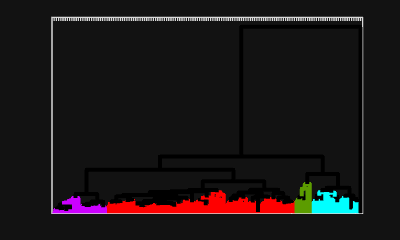

% X1
% Generate HC with average linkage
%============================================
%
%============================================

tree1=linkage(numericX1,'average');
clusterAssignments = cluster(tree1, 'MaxClust', 5);
%
writematrix(nClusters, "mlab_clusters_X1.csv")
% Generate figure with 4 clusters
%
figure
cutoff = median([tree1(end-nClusters+1,3) tree1(end-nClusters+2, 3)]);
h1=dendrogram(tree1,0,'ColorThreshold',cutoff);
set(h1,'LineWidth',1.5);
xticklabels([])
yticks([])
% xlabel({"X1 Average Linkage"});
% yticklabels({});
box on
gca.LineWidth=1;
%
% Collect colors
%
% We use four colors, that are in order:
% Cluster 1: red
% Cluster 2: purple
% Cluster 3: cyan
% Cluster 4: green
%
cyan=[0 1.0 1.0];
lineColours1 = cell2mat(get(h1,'Color'));
colorList1 = unique(lineColours1, 'rows');

%colorList(9,:) = [1 0 1];
for iLeaf = 1:N
	[iRow, ~] = find(tree1==iLeaf);
	color = lineColours1(iRow,:);
	% assign color to each observation
	numericX1_cluster(iLeaf,1) = iLeaf;
	numericX1_cluster(iLeaf,2) = find(ismember(colorList1, color, 'rows')); 
    numericX1_color(iLeaf,:) = X1_cols(clusterAssignments(iLeaf),:); 
end
for i = 1:length(h1)
        h1(i).Color = [0, 0, 0]; % RGB for black
end
for iLeaf = 1:N
    [iRow, ~] = find(tree1==iLeaf);
    set(h1(iRow), 'Color', numericX1_color(iLeaf,:));
end

% savefig("X1_average.fig");
% exportgraphics(gcf, 'X1_average.png');

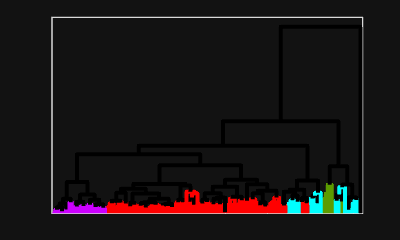



%
%============================================
% Generate HC with complete linkage
%============================================
%
tree2=linkage(numericX1,'complete');
%
% Generate clustering and drendrogram
%
figure
h2=dendrogram(tree2,0);
set(h2,'Color','k');
set(h2,'LineWidth',1.5);
for i = 1:length(h2)
    h2(i).Color = [0, 0, 0]; % RGB for black
end
% 
% Recolor based on colors of average clustering
%
for iLeaf = 1:N
	[iRow, ~] = find(tree2==iLeaf);
	set(h2(iRow), 'Color', numericX1_color(iLeaf,:));
end
xticks([])
yticks([])
% xlabel({"X1 Complete Linkage"});
% yticklabels({});
box on

gca.LineWidth=1;

savefig("X1_complete.fig");
exportgraphics(gcf, 'X1_complete.png');

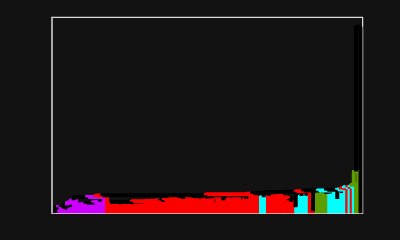


%============================================
% Generate HC with single linkage
%============================================
%
tree3=linkage(numericX1,'single');
%
% Generate clustering and drendrogram
%
figure
h3=dendrogram(tree3,0);
set(h3,'Color','k');
set(h3,'LineWidth',1.5);
% 
% Recolor based on colors of average clustering
%
for i = 1:length(h3)
    h3(i).Color = [0, 0, 0]; % RGB for black
end
for iLeaf = 1:N
	[iRow, ~] = find(tree3==iLeaf);
	set(h3(iRow), 'Color', numericX1_color(iLeaf,:));
end
xticks([])
yticks([])
% xlabel({"X1 Single Linkage"});
% yticklabels({});
box on

gca.LineWidth=1;
for i = 1:size(h3,1)
    if h3(i).Color == [0.5 1.0 0];
        h3(i).Color = [0.36 0.61 0.00];
    end
end
savefig("X1_single.fig");
exportgraphics(gcf, 'X1_single.png');


%============================================
% Generate HC with single linkage
%============================================
%
tree4=linkage(numericX1,'ward');
%
% Generate clustering and drendrogram
%
figure
h4=dendrogram(tree4,0);
set(h4,'Color','k')
set(h4,'LineWidth',1.5)
% 
% Recolor based on colors of average clustering
%
for i = 1:length(h4)
    h4(i).Color = [0, 0, 0]; % RGB for black
end
for iLeaf = 1:N
	[iRow, ~] = find(tree4==iLeaf);
	set(h4(iRow), 'Color', numericX1_color(iLeaf,:));
end
xticks([])
yticks([])
% xlabel({"X1 Ward Linkage"});
% yticklabels({});
box on
gca.LineWidth=1;
for i = 1:size(h4,1)
    if h4(i).Color == [0.5 1.0 0];
        h4(i).Color = [0.36 0.61 0.00];
    end
end
savefig("X1_ward.fig");
exportgraphics(gcf, 'X1_ward.png');


%============================================
% Perform MDS
%============================================
%
[Y e]=cmdscale(numericX1,2);

figure
hold on
for i=1:N
    for i=1:N
     plot (Y(i,1),Y(i,2), "o", "Color", numericX1_color(i,:), 'LineWidth',1.5);
    % plot(Y(iLeaf,1),Y(iLeaf,2), 'o','Color',numericY1_color(iLeaf,:), 'LineWidth',1.5);
end
    % plot(Y(iLeaf,1),Y(iLeaf,2), 'o','Color',numericX1_color(iLeaf,:), 'LineWidth',1.5);
end
xticks([])
% yticks([])
% xlabel({"X1 MDS"});
% yticklabels({});
box on
gca.LineWidth=1;
savefig("X1_mds.fig");
exportgraphics(gcf, 'X1_mds.png');